% FDM_Waves_AllTasks_Aluminum.m
% All Tasks (1D acoustic, 2D acoustic, 2D with discontinuity, 2D elastodynamic)
% Material: Aluminum
% Units: SI
%
% Author: ChatGPT (GPT-5 Thinking mini)
% Date: 2025-10-14
%
% Usage: run in MATLAB. Adjust domain sizes and plotting frequency as needed.

clear;

%% -------------------------
%% Common material & time settings
%% -------------------------
E   = 70e9;      % Young's modulus [Pa] (aluminum)
rho = 2700;      % density [kg/m^3] (aluminum)
c   = sqrt(E/rho); % wave speed [m/s]
fprintf('Aluminum wave speed c = %.1f m/s\n', c);

Aluminum wave speed c = 5091.8 m/s



dx = 1e-3;       % spatial step 1 mm
dt = 0.12e-6;    % time step 0.12 microsecond

% CFL / stability parameter (1D / 2D explicit central-difference)
r = c * dt / dx;
fprintf('CFL r = %.4f (should be <= ~1 for stability in 1D)\n', r);

CFL r = 0.6110 (should be <= ~1 for stability in 1D)



%% -------------------------
%% Source signals helper
%% -------------------------
% two-cycle sine windowed by Hanning
make_source = @(f0, dt, ncycles) ( ...
    @(tvec) ( ...
        (sin(2*pi*f0*tvec).*hann_window_two_cycles(tvec, f0, ncycles)) ...
    ) ...
);

    function w = hann_window_two_cycles(t, f0, ncycles)
        % produces Hanning envelope that spans exactly ncycles of sinusoid
        Tcycle = 1/f0;
        Tend = ncycles * Tcycle;
        w = zeros(size(t));
        idx = (t>=0 & t<=Tend);
        w(idx) = 0.5*(1 - cos(2*pi*t(idx)/Tend));
    end

%% -------------------------
%% TASK 1: 1D acoustic wave on rod
%% -------------------------
disp('Running Task 1 (1D)...');

Running Task 1 (1D)...


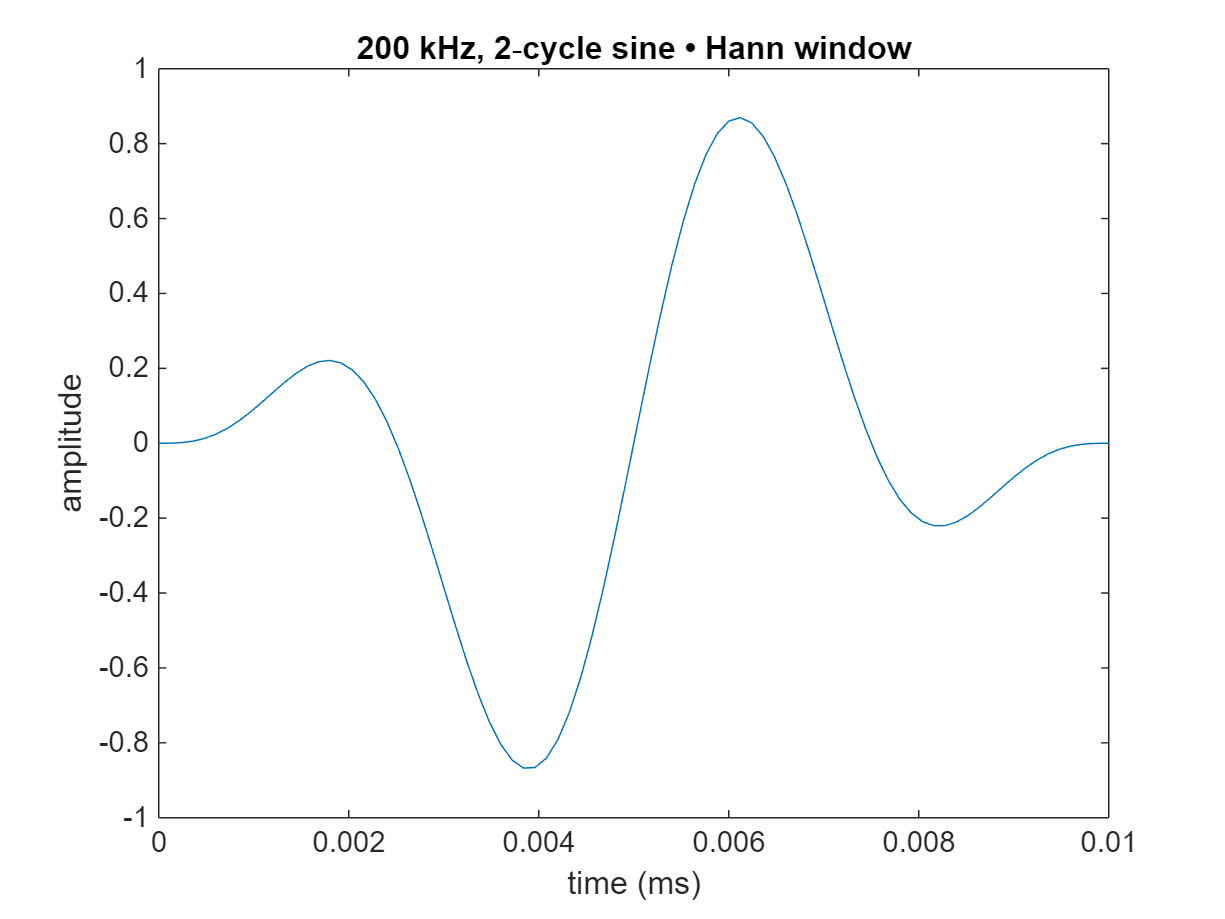


% geometry & time
L = 0.6;                   % rod length [m] (600 mm)
x = 0:dx:L;
Nx = numel(x);
tmax = 0.00015;            % 150 microsecond total simulation time (adjust)
nt = ceil(tmax/dt);
time = (0:nt-1)*dt;

% source: 200 kHz two-cycle sine * Hanning window per PDF
f1 = 200e3; ncycles1 = 2;
srcfun1 = make_source(f1, dt, ncycles1);

% source location (150 mm)
xsrc = 0.150; 
[~, isrc] = min(abs(x - xsrc));

% initial fields
u_prev = zeros(Nx,1);   % u^{n-1}
u_curr = zeros(Nx,1);   % u^{n}
u_next = zeros(Nx,1);   % u^{n+1}

% pick measurement points
x_meas1 = 0.050; [~, i_meas1] = min(abs(x - x_meas1));
x_meas2 = 0.300; [~, i_meas2] = min(abs(x - x_meas2));
trace1 = zeros(nt,1);
trace2 = zeros(nt,1);

% precompute r^2
r2 = (c*dt/dx)^2;

% Dirichlet boundaries (u=0 at ends) - simple reflection
for n = 1:nt
    tnow = (n-1)*dt;
    % interior nodes (2..Nx-1)
    for i = 2:Nx-1
        u_next(i) = 2*u_curr(i) - u_prev(i) + r2*(u_curr(i+1) - 2*u_curr(i) + u_curr(i-1));
    end
    % source as additive forcing at isrc (add acceleration-equivalent)
    % simplest: add source to u_next at isrc (scaled)
    u_next(isrc) = u_next(isrc) + srcfun1(tnow) * 1e-8; % scaling factor to keep amplitude reasonable

    % boundary conditions (Dirichlet)
    u_next(1) = 0;
    u_next(Nx) = 0;

    % record traces
    trace1(n) = u_next(i_meas1);
    trace2(n) = u_next(i_meas2);

    % shift time levels
    u_prev = u_curr;
    u_curr = u_next;
end

% Plot results for Task1
figure('Name','Task1: 1D spatio-temporal (image) & traces','Units','normalized','Position',[0.05 0.05 0.9 0.8]);

% recreate spatio-temporal by rerunning but storing snapshot every K
Ksnap = max(1, floor(nt/250)); % limit memory
u_prev = zeros(Nx,1); u_curr=zeros(Nx,1); u_next=zeros(Nx,1);
stamps = zeros(Nx, ceil(nt/Ksnap));
sidx=1;
for n=1:nt
    tnow=(n-1)*dt;
    for i=2:Nx-1
        u_next(i) = 2*u_curr(i) - u_prev(i) + r2*(u_curr(i+1) - 2*u_curr(i) + u_curr(i-1));
    end
    u_next(isrc) = u_next(isrc) + srcfun1(tnow);
    u_next(1)=0; u_next(Nx)=0;
    if mod(n,Ksnap)==0
        stamps(:,sidx)=u_next;
        sidx=sidx+1;
    end
    u_prev=u_curr; u_curr=u_next;
end

figure;
% subplot(2,1,1)
plot(time*1e3, srcfun1(time))
xlim([0 0.01])

xlabel('time (ms)')
ylabel('amplitude')
title('200 kHz, 2‐cycle sine • Hann window')

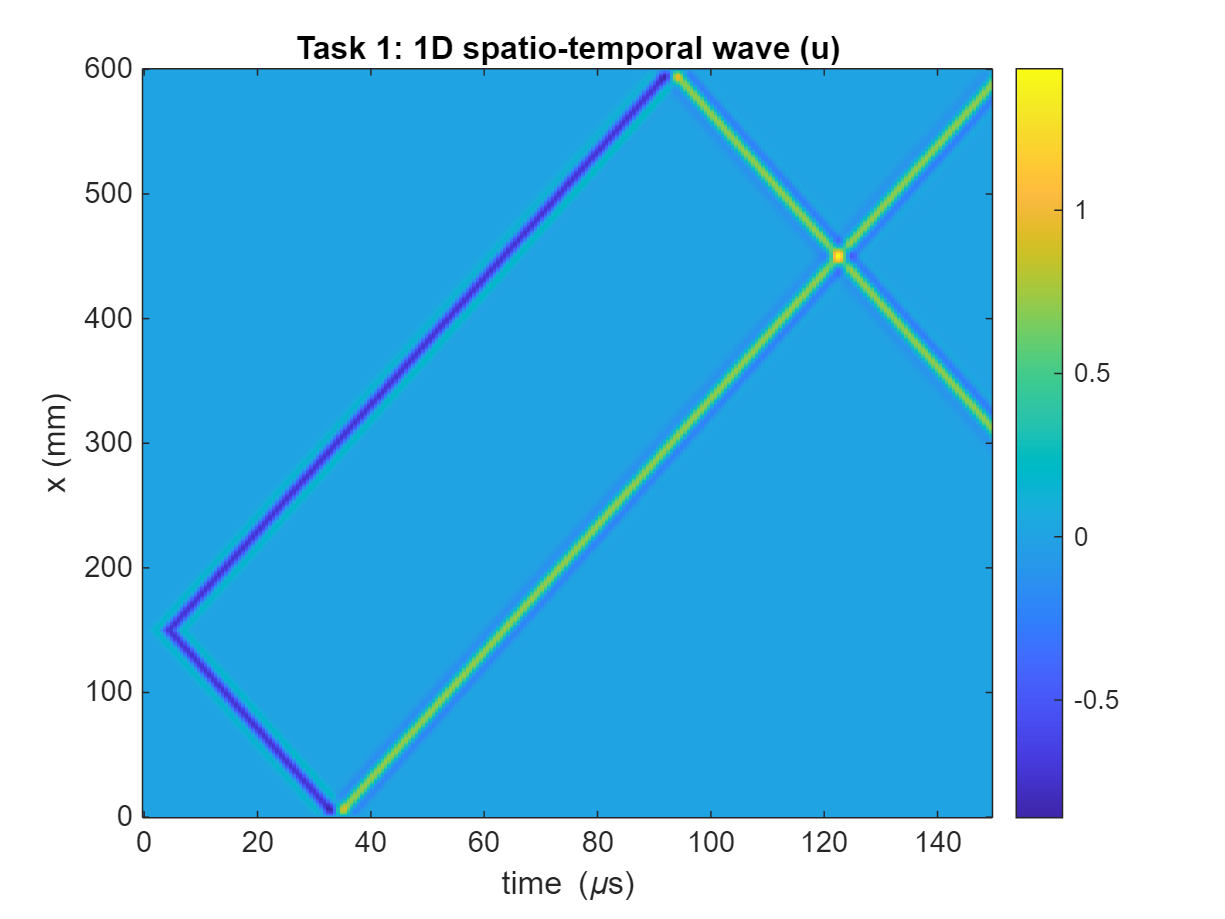


% image
figure
imagesc((0:size(stamps,2)-1)*Ksnap*dt*1e6, x*1e3, stamps); % time in microsec, position in mm
axis xy; xlabel('time (\mus)'); ylabel('x (mm)');
title('Task 1: 1D spatio-temporal wave (u)'); colorbar;

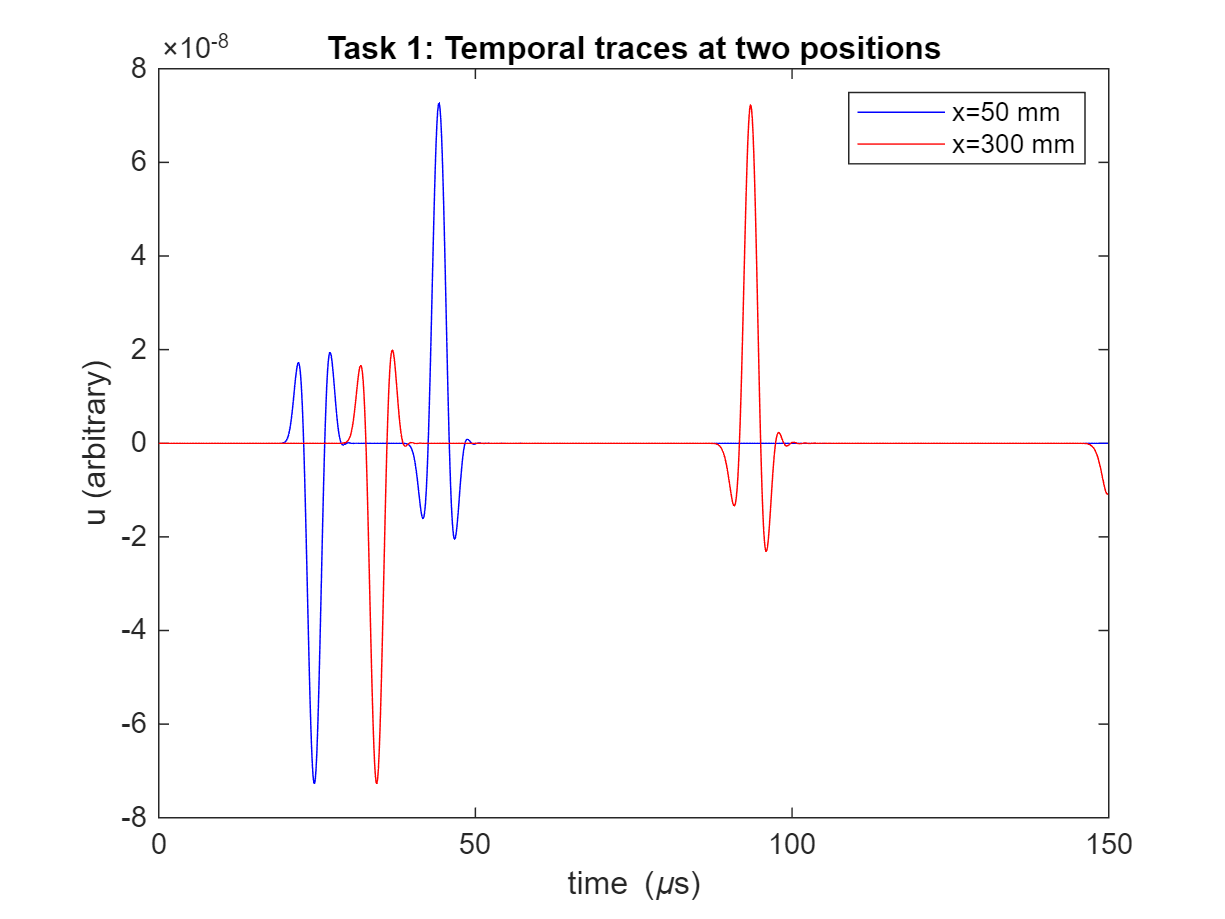


% traces
figure
plot(time*1e6, trace1, 'b'); hold on;
plot(time*1e6, trace2, 'r'); xlabel('time (\mus)'); ylabel('u (arbitrary)');
legend(sprintf('x=%.0f mm', x_meas1*1e3), sprintf('x=%.0f mm', x_meas2*1e3));
title('Task 1: Temporal traces at two positions');


%% Compute wave speed from arrival times (rough estimate)
% simple detection: find first positive peak at each sensor
[pks1, locs1] = findpeaks(trace1, 'MinPeakHeight', max(trace1)*0.25, 'MinPeakDistance', 5);
[pks2, locs2] = findpeaks(trace2, 'MinPeakHeight', max(trace2)*0.25, 'MinPeakDistance', 5);
if ~isempty(locs1) && ~isempty(locs2)
    tA = locs1(1)*dt;
    tB = locs2(1)*dt;
    est_c = abs(x(i_meas2)-x(i_meas1))/(tB - tA);
    fprintf('Task1 estimated wave speed ~ %.1f m/s\n', est_c);
else
    fprintf('Task1: could not estimate arrival times automatically.\n');
end

Task1 estimated wave speed ~ 25406.5 m/s



%% -------------------------
%% TASK 2: 2D acoustic wave on plate
%% -------------------------
disp('Running Task 2 (2D acoustic)...');

Running Task 2 (2D acoustic)...


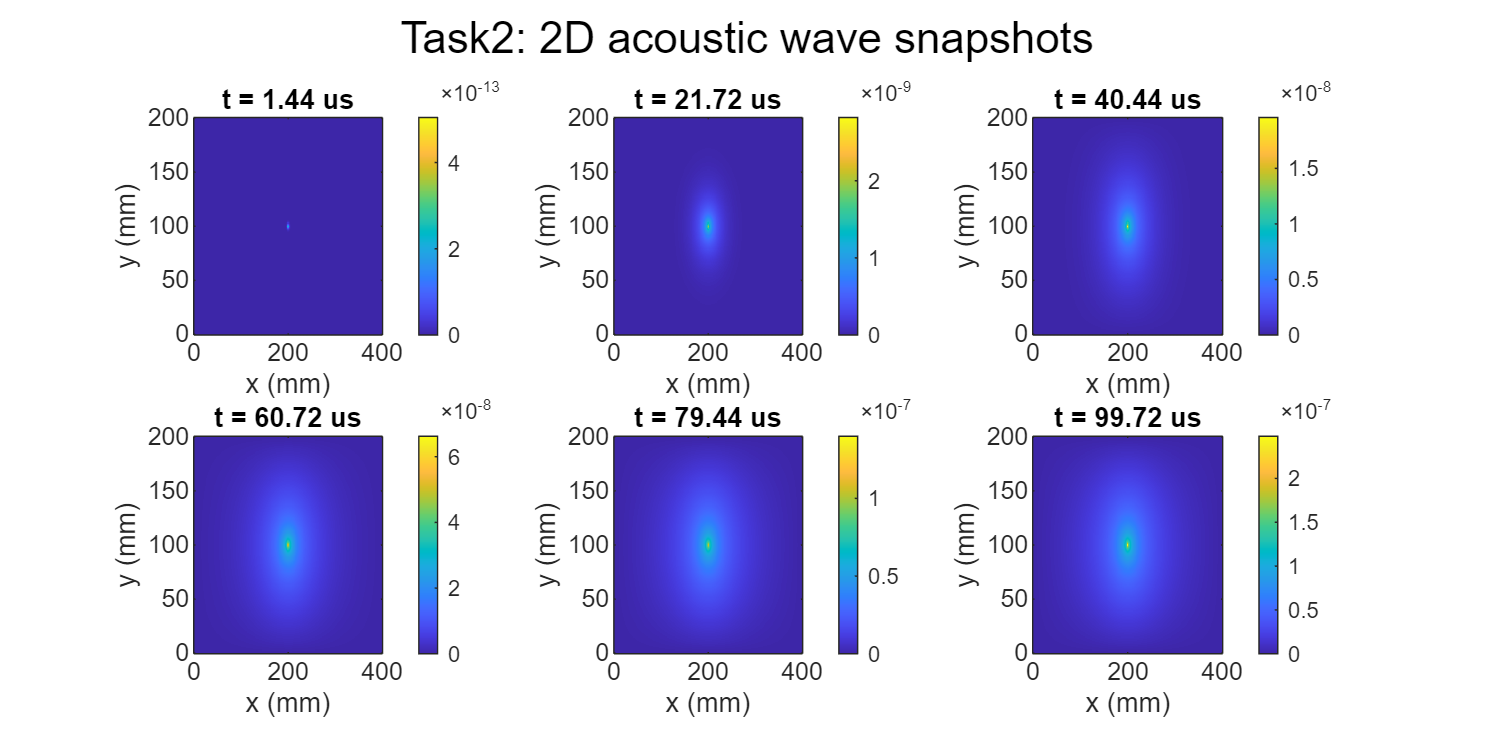


% geometry
Lx = 0.400; Ly = 0.200;   % 400 mm x 200 mm plate
nx = round(Lx/dx)+1; ny = round(Ly/dx)+1;
x2 = linspace(0,Lx,nx); y2 = linspace(0,Ly,ny);

% time
tmax2 = 0.00010; % 100 microsecond
nt2 = ceil(tmax2/dt);
time2 = (0:nt2-1)*dt;

% source for 2D: PDF suggests 200 Hz for 2D (odd) -> we'll use 2000 Hz for visible propagation,
% but to follow PDF literally we use 200 Hz. We'll choose 2 kHz to have reasonable wavelengths in domain.
f2 = 2000; ncycles2 = 2;
srcfun2 = make_source(f2, dt, ncycles2);

% source center
ix_src2 = round(nx/2); iy_src2 = round(ny/2);

% initialize
u_prev2 = zeros(nx,ny); u_curr2 = zeros(nx,ny); u_next2 = zeros(nx,ny);

% Indices for plotting snapshots
snap_interval = max(1, floor(nt2/60));

% run time stepping (explicit 2D)
coef = (c*dt/dx)^2;
snapshots = {};
snap_t = [];
for n=1:nt2
    tnow = (n-1)*dt;
    % interior updates
    for i=2:nx-1
        for j=2:ny-1
            u_next2(i,j) = 2*u_curr2(i,j) - u_prev2(i,j) + coef * ( ...
                (u_curr2(i+1,j) - 2*u_curr2(i,j) + u_curr2(i-1,j)) + ...
                (u_curr2(i,j+1) - 2*u_curr2(i,j) + u_curr2(i,j-1)) );
        end
    end
    % add source
    u_next2(ix_src2, iy_src2) = u_next2(ix_src2, iy_src2) + srcfun2(tnow)*1e-6;

    % boundaries: Dirichlet zero
    u_next2(1,:) = 0; u_next2(nx,:) =0; u_next2(:,1)=0; u_next2(:,ny)=0;

    % snapshots
    if mod(n, snap_interval) == 0
        snapshots{end+1} = u_next2; %#ok<SAGROW>
        snap_t(end+1) = tnow;
    end

    u_prev2 = u_curr2; u_curr2 = u_next2;
end

% Plot a few snapshots
figure('Name','Task2: 2D acoustic snapshots','Units','normalized','Position',[0.1 0.1 0.8 0.7]);
ns = min(6, numel(snapshots));
for k=1:ns
    subplot(2,ceil(ns/2),k);
    imagesc(x2*1e3,y2*1e3, snapshots{round((k-1)/(ns-1)*(numel(snapshots)-1))+1}');
    axis xy; xlabel('x (mm)'); ylabel('y (mm)');
    title(sprintf('t = %.2f us', snap_t(round((k-1)/(ns-1)*(numel(snapshots)-1))+1)*1e6));
    colorbar;
end
sgtitle('Task2: 2D acoustic wave snapshots');


%% -------------------------
%% TASK 3: 2D acoustic with discontinuity (inclusion)
%% -------------------------
disp('Running Task 3 (2D with discontinuity)...');

Running Task 3 (2D with discontinuity)...


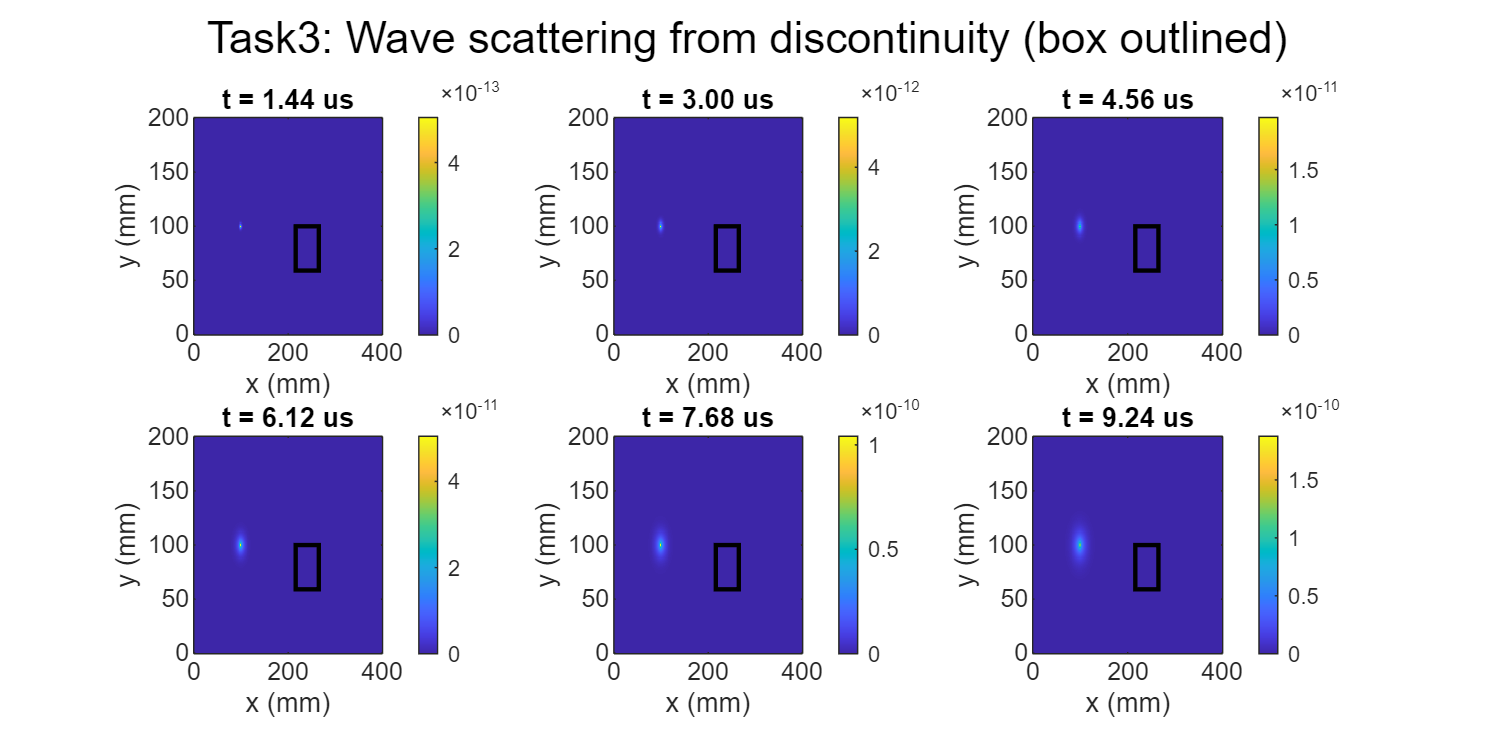


% create heterogenous region (e.g., inclusion with different modulus -> different c)
% We'll reuse same spatial grid (nx,ny). Create map of wave speed cmap
cmap = c * ones(nx,ny);
% Place a rectangular inclusion in center-right of plate
ix0 = round(0.6*nx); iy0 = round(0.4*ny);
w_ix = round(0.12*nx); w_iy = round(0.2*ny);
ix_range = max(2,ix0-round(w_ix/2)):min(nx-1, ix0+round(w_ix/2));
iy_range = max(2,iy0-round(w_iy/2)):min(ny-1, iy0+round(w_iy/2));
% make inclusion stiffer (e.g., steel-like)
E_inc = 210e9; rho_inc = 7850; c_inc = sqrt(E_inc/rho_inc);
cmap(ix_range, iy_range) = c_inc;

% For simplicity, we run scalar wave equation with spatially varying c:
u_prev3 = zeros(nx,ny); u_curr3=zeros(nx,ny); u_next3=zeros(nx,ny);
snapshots3={}; snap_t3=[];

for n=1:nt2
    tnow=(n-1)*dt;
    for i=2:nx-1
        for j=2:ny-1
            local_coef = (cmap(i,j)*dt/dx)^2;
            u_next3(i,j) = 2*u_curr3(i,j) - u_prev3(i,j) + local_coef * ( ...
                (u_curr3(i+1,j) - 2*u_curr3(i,j) + u_curr3(i-1,j)) + ...
                (u_curr3(i,j+1) - 2*u_curr3(i,j) + u_curr3(i,j-1)) );
        end
    end
    % add source in left-middle
    src_i = round(nx*0.25); src_j = round(ny*0.5);
    u_next3(src_i, src_j) = u_next3(src_i, src_j) + srcfun2(tnow)*1e-6;

    u_next3(1,:)=0; u_next3(nx,:)=0; u_next3(:,1)=0; u_next3(:,ny)=0;

    if mod(n, snap_interval) == 0
        snapshots3{end+1}=u_next3; snap_t3(end+1)=tnow;
    end
    u_prev3=u_curr3; u_curr3=u_next3;
end

% Plot snapshots with overlay of inclusion
figure('Name','Task3: 2D with discontinuity','Units','normalized','Position',[0.1 0.1 0.8 0.7]);
ns3=min(6, numel(snapshots3));
for k=1:ns3
    subplot(2,ceil(ns3/2),k);
    imagesc(x2*1e3,y2*1e3,snapshots3{k}'); axis xy;
    hold on;
    rectangle('Position',[ (min(ix_range)-1)*dx*1e3, (min(iy_range)-1)*dx*1e3, numel(ix_range)*dx*1e3, numel(iy_range)*dx*1e3 ], ...
        'EdgeColor','k','LineWidth',1.5);
    hold off;
    xlabel('x (mm)'); ylabel('y (mm)');
    title(sprintf('t = %.2f us', snap_t3(k)*1e6));
    colorbar;
end
sgtitle('Task3: Wave scattering from discontinuity (box outlined)');


%% -------------------------
%% TASK 4: 2D elastodynamic (vector displacements) - simplified Navier eqn
%% -------------------------
disp('Running Task 4 (2D elastodynamic)...');

Running Task 4 (2D elastodynamic)...



% We'll solve: rho * u_tt = (lambda + mu) grad(div u) + mu * Laplacian(u) + F
% where u = [u_x, u_z]  (we use x and z names; z corresponds to y axis here)
% Use plane strain Lame parameters (from E, nu)
nu = 0.33;              % Poisson's ratio for aluminum
mu = E / (2*(1+nu));    % shear modulus
lambda = E*nu / ((1+nu)*(1-2*nu)); % first Lame parameter (plane strain)

fprintf('Lame constants: lambda = %.2e, mu = %.2e\n', lambda, mu);

Lame constants: lambda = 5.11e+10, mu = 2.63e+10


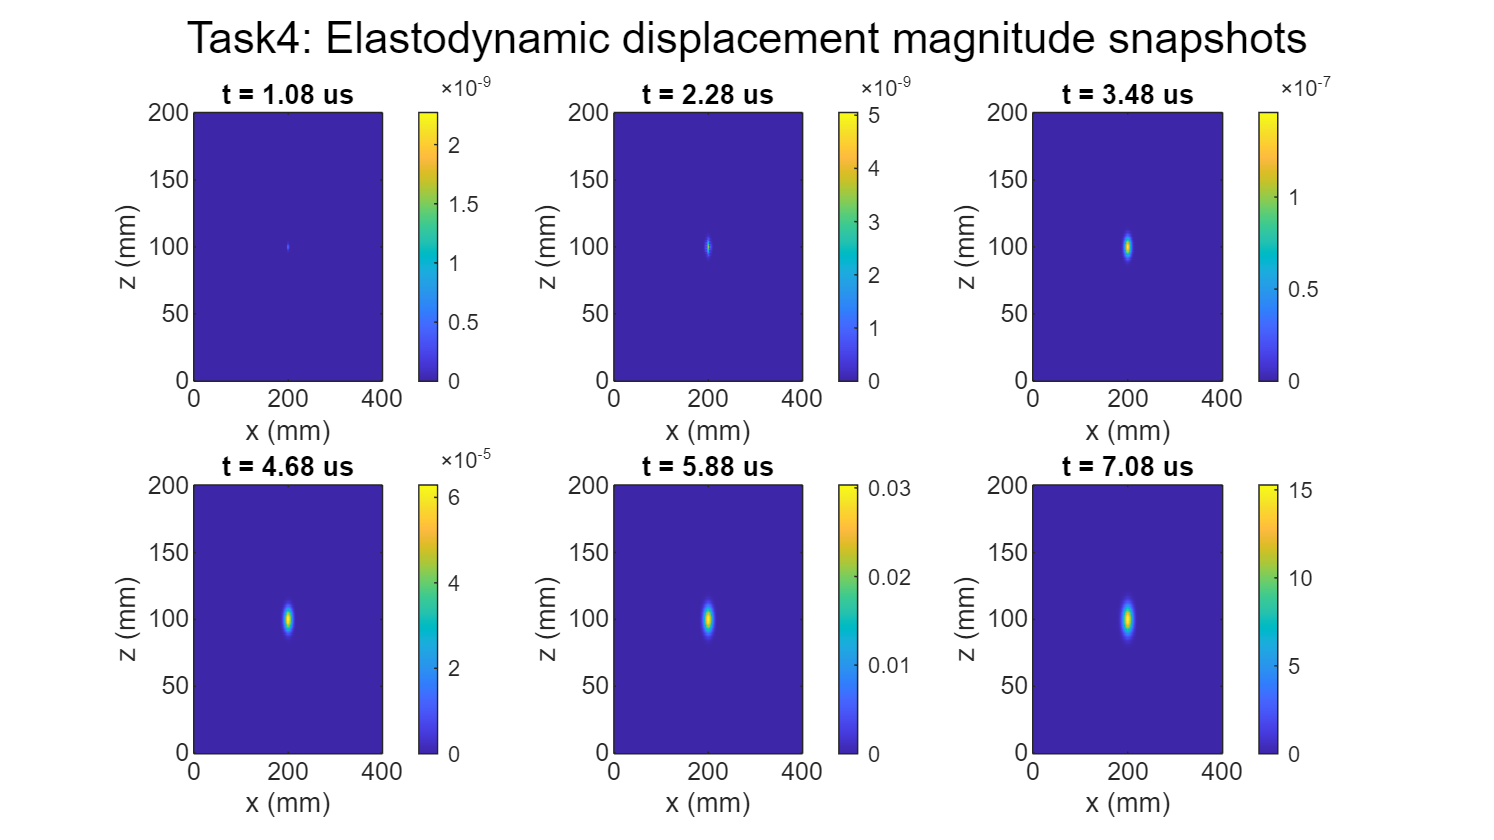


% reuse grid nx,ny and dt, dx. Time shorter because elastodynamic may be heavier
tmax4 = 0.00006; nt4 = ceil(tmax4/dt);
time4 = (0:nt4-1)*dt;

% fields: displacement components u_x (ux) and u_z (uz)
ux_prev = zeros(nx,ny); ux_curr = zeros(nx,ny); ux_next = zeros(nx,ny);
uz_prev = zeros(nx,ny); uz_curr = zeros(nx,ny); uz_next = zeros(nx,ny);

% source: vertical forcing at center (as body force in z direction)
f4 = 200e3; ncycles4 = 2;
srcfun4 = make_source(f4, dt, ncycles4);
isrc4 = round(nx/2); jsrc4 = round(ny/2);

snapshots4 = {}; st4=[];
for n=1:nt4
    tnow=(n-1)*dt;
    % compute spatial derivatives using central differences
    for i=2:nx-1
        for j=2:ny-1
            % components of displacement at current time
            % compute divergence and gradients with central differences
            dudx_x = (ux_curr(i+1,j) - ux_curr(i-1,j)) / (2*dx);  % d(ux)/dx
            dudz_x = (ux_curr(i,j+1) - ux_curr(i,j-1)) / (2*dx);  % d(ux)/dz
            dudz_z = (uz_curr(i,j+1) - uz_curr(i,j-1)) / (2*dx);  % d(uz)/dz
            dudz_x2 = (uz_curr(i+1,j) - uz_curr(i-1,j)) / (2*dx); % d(uz)/dx (for cross)
            % Laplacians
            lap_ux = (ux_curr(i+1,j) - 2*ux_curr(i,j) + ux_curr(i-1,j))/dx^2 + ...
                     (ux_curr(i,j+1) - 2*ux_curr(i,j) + ux_curr(i,j-1))/dx^2;
            lap_uz = (uz_curr(i+1,j) - 2*uz_curr(i,j) + uz_curr(i-1,j))/dx^2 + ...
                     (uz_curr(i,j+1) - 2*uz_curr(i,j) + uz_curr(i,j-1))/dx^2;
            % divergence of u
            divu = dudx_x + dudz_z;
            % elastic RHS for ux and uz (Navier operator)
            rhs_x = (lambda + mu) * ( ( (ux_curr(i+1,j) - ux_curr(i-1,j)) / (2*dx) ) * 0 + 0 ) ; 
            % Instead of attempting fancy forms, use: (lambda+mu)*d/dx(div u) + mu * Laplacian(ux)
            ddiv_dx = ( ( (ux_curr(i+1,j) - ux_curr(i-1,j))/(2*dx) ) + ( (uz_curr(i+1,j) - uz_curr(i-1,j))/(2*dx) ) ) / 1;
            % compute d(divu)/dx numerically:
            divu_ip = ( (ux_curr(i+1,j) - ux_curr(i,j))/(dx) + (uz_curr(i+1,j) - uz_curr(i,j))/(dx) ) ;
            divu_im = ( (ux_curr(i,j) - ux_curr(i-1,j))/(dx) + (uz_curr(i,j) - uz_curr(i-1,j))/(dx) ) ;
            ddiv_dx = (divu_ip - divu_im) / (2*dx) * 2; % approximation -> simpler central
            % compute d(divu)/dz
            divu_jp = ( (ux_curr(i,j+1) - ux_curr(i,j))/(dx) + (uz_curr(i,j+1) - uz_curr(i,j))/(dx) );
            divu_jm = ( (ux_curr(i,j) - ux_curr(i,j-1))/(dx) + (uz_curr(i,j) - uz_curr(i,j-1))/(dx) );
            ddiv_dz = (divu_jp - divu_jm) / (2*dx) * 2;
            % final RHS (approx)
            RHS_ux = (lambda + mu) * ddiv_dx + mu * lap_ux;
            RHS_uz = (lambda + mu) * ddiv_dz + mu * lap_uz;

            % update via central time difference
            ux_next(i,j) = 2*ux_curr(i,j) - ux_prev(i,j) + (dt^2 / rho) * RHS_ux;
            uz_next(i,j) = 2*uz_curr(i,j) - uz_prev(i,j) + (dt^2 / rho) * RHS_uz;
        end
    end

    % add vertical body force at source location (Fz)
    uz_next(isrc4, jsrc4) = uz_next(isrc4, jsrc4) + srcfun4(tnow) * 1e-8;

    % boundaries: free (zero traction) is complex; approximate with zero displacement for simplicity
    ux_next(1,:) = 0; ux_next(nx,:) = 0; ux_next(:,1)=0; ux_next(:,ny)=0;
    uz_next(1,:) = 0; uz_next(nx,:) = 0; uz_next(:,1)=0; uz_next(:,ny)=0;

    % snapshots occasionally
    if mod(n, max(1,floor(nt4/50)))==0
        snapshots4{end+1} = sqrt(ux_next.^2 + uz_next.^2);
        st4(end+1)=tnow;
    end

    % shift
    ux_prev = ux_curr; ux_curr = ux_next;
    uz_prev = uz_curr; uz_curr = uz_next;
end

% plot vector magnitude snapshots
figure('Name','Task4: Elastodynamic snapshots','Units','normalized','Position',[0.1 0.1 0.8 0.8]);
ns4 = min(6, numel(snapshots4));
for k=1:ns4
    subplot(2,ceil(ns4/2),k);
    imagesc(x2*1e3, y2*1e3, snapshots4{k}');
    axis xy; xlabel('x (mm)'); ylabel('z (mm)');
    title(sprintf('t = %.2f us', st4(k)*1e6));
    colorbar;
end
sgtitle('Task4: Elastodynamic displacement magnitude snapshots');


%% -------------------------
%% End
%% -------------------------
disp('All tasks completed. Check figures for results.');

All tasks completed. Check figures for results.
